close all
clear all 
clc

params;

% Initial conditions
theta_1_0 = pi/4;
theta_2_0 = 0;
theta_3_0 = pi/2;
theta_dot_1_0 = 0;
theta_dot_2_0 = 0;
theta_dot_3_0 = 0;

t = (0:0.1:1)';

% ODE45 settings
options = odeset('abstol', 1E-7, 'reltol', 1E-7);
z_0 = [theta_1_0; theta_2_0; theta_3_0; theta_dot_1_0; theta_dot_2_0; theta_dot_3_0];
[time, z] = ode45('manipulator', t, z_0, options);

Error using nargin
File: manipulator.m Line: 71 Column: 19
Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

Error in odearguments (line 60)
    if (nargin(ode) == 2)           

Error in 

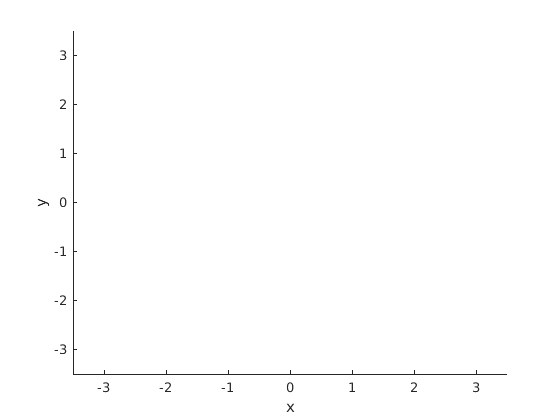

% Get varibles from simulation
theta_1 = z(:,1);
theta_2 = z(:,2);
theta_3 = z(:,3);

hold on 
plot(t,theta_1)
plot(t,theta_2)
hold off


% Calculating link endpoints
L1_x = a_1*cos(theta_1);
L1_y = a_1*sin(theta_1);
L2_x = L1_x + a_2*cos(theta_1+theta_2);
L2_y = L1_y + a_2*sin(theta_1+theta_2);
L3_x = L2_x + a_3*cos(theta_1+theta_2+theta_3);
L3_y = L2_y + a_3*sin(theta_1+theta_2+theta_3);

tempcmd = sprintf('h = figure(''name'',''Part b: Animation of Planar 2R manip (no control torques)'', ''NumberTitle'',''off'');');
eval(tempcmd);
axis([-3.5 3.5 -3.5 3.5]);
xlabel('x');
ylabel('y');

L1_line = line('xdata', [0, L1_x(1)], 'ydata', [0, L1_y(1)],...
    'linewidth', 3, 'erase', 'xor', 'color', 'blue');

L2_line = line('xdata', [L1_x(1), L2_x(1)], 'ydata', [L1_y(1), L2_y(1)],...
    'linewidth', 3, 'erase', 'xor', 'color', 'red');

L3_line = line('xdata', [L2_x(1), L3_x(1)], 'ydata', [L2_y(1), L3_y(1)],...
    'linewidth', 3, 'erase', 'xor', 'color', 'red');


% Slow down factor for graphics
delay = 150;

hold on
% Draw and redraw the objects with new xdata, ydata
for i=1:length(time)
    for j=1:100 % Arbitrary FOR-LOOP for delayed graphics
        log(1:delay);
    end
    set(L1_line, 'xdata', [      0, L1_x(i)], 'ydata', [      0, L1_y(i)]);
    set(L2_line, 'xdata', [L1_x(i), L2_x(i)], 'ydata', [L1_y(i), L2_y(i)]);
    set(L3_line, 'xdata', [L2_x(i), L3_x(i)], 'ydata', [L2_y(i), L3_y(i)]);
    drawnow;
end


hold off